# [Automotive Monitoring](https://apmonitor.com/pds/index.php/Main/AutomotiveMonitoring)

**Background:** [**Automotive data**](https://apmonitor.com/pds/uploads/Main/automotive.txt) is available from [**OBD-II codes**](https://en.wikipedia.org/wiki/OBD-II_PIDs) that are standard for engine monitoring of light duty vehicles (passenger cars) starting in year 1996. Newer vehicles may include additional sensors from other electronic systems such as the brake system, tire pressure, climate control, and transmission. Data is processed with on-board computers to monitor the health of the vehicle systems and provide warning diagnostics when there is an indication of malfunction.

**Objective:** Investigate driver and automobile performance. Use an OBD-II reader and collect data from a vehicle. Analyze the following:

- Determine Light-off Time of the Catalytic Converter

- Visualize the Speed and Elevation on a Map

- Find maximum fuel economy versus speed

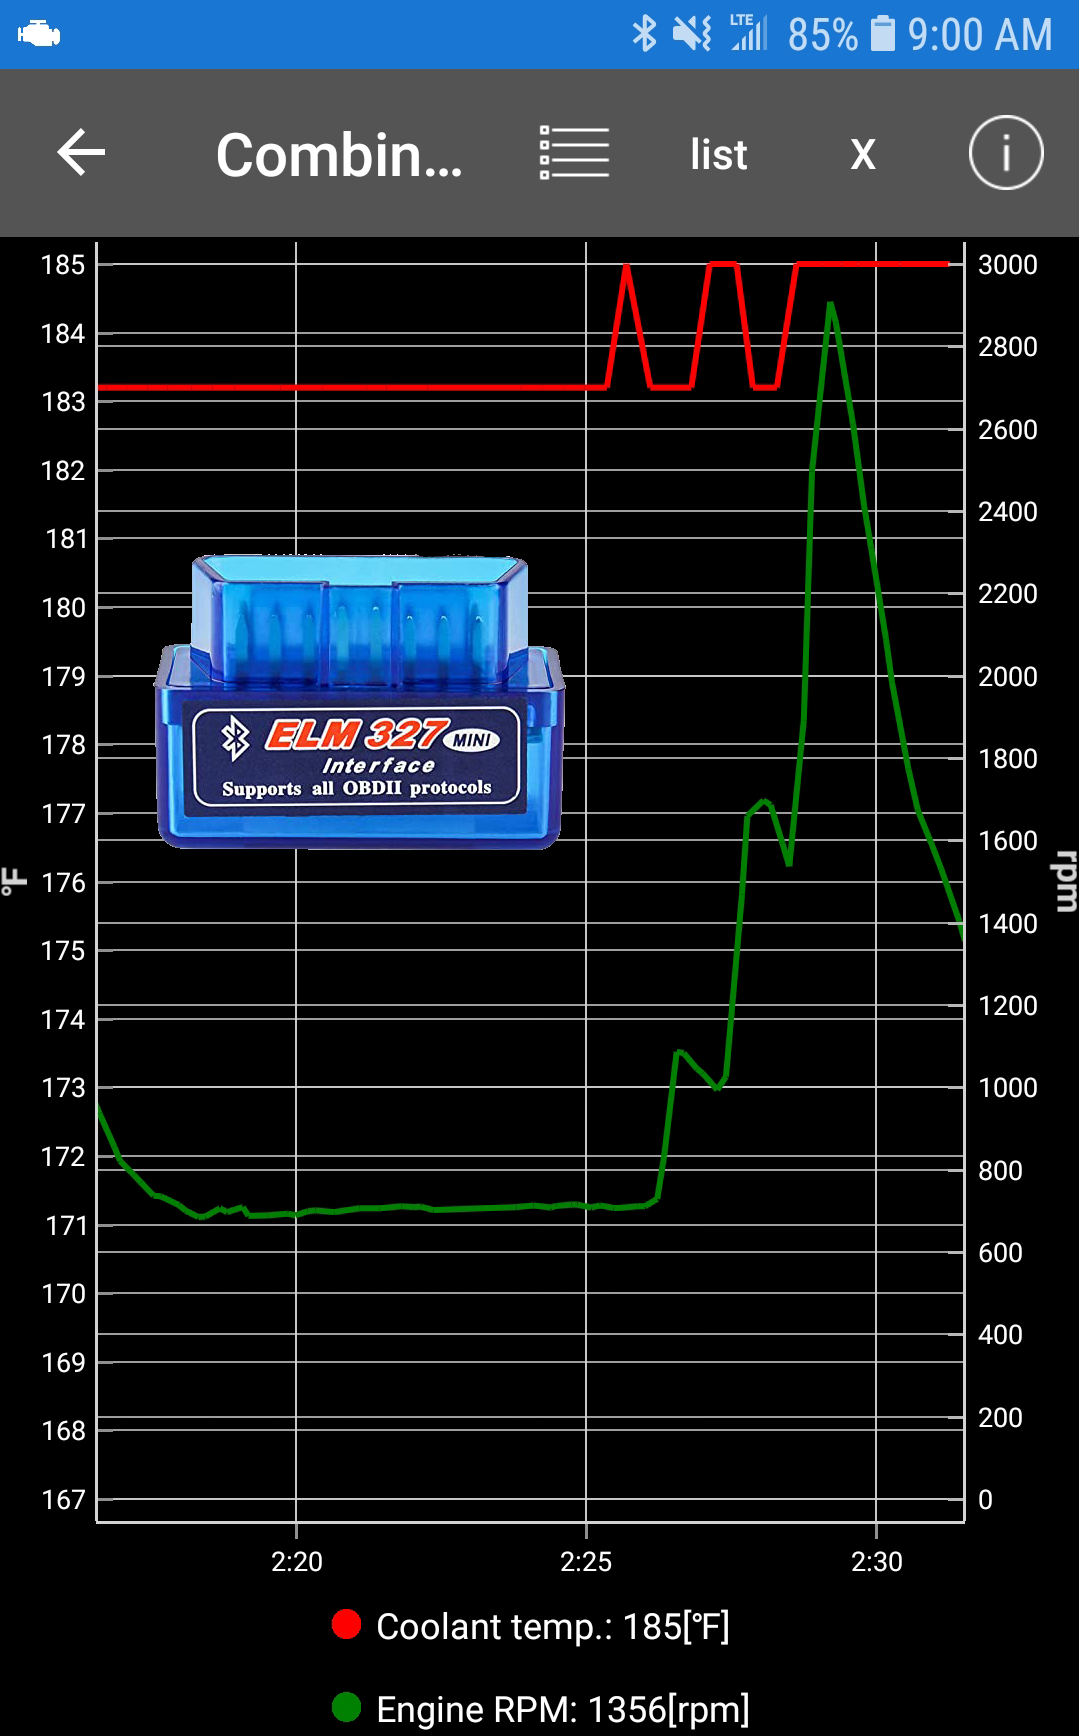

## Data Collection

Data was collected from a 2014 Ford Focus (manual transmission) with city and freeway driving on Sept 21, 2021 for a round-trip from Provo to Salt Lake City, Utah. There are 22 data columns with raw sensor data and calculated values that were collected with Car Scanner (App) from the OBD-II codes over a BlueTooth connection.

% Load the data from a url
url = 'http://apmonitor.com/pds/uploads/Main/automotive.txt';

% Read the csv file and store it in a table
data = readtable(url, "VariableNamingRule", "preserve");

% View a sample of the data
disp(data(1:10,:))

        time        Average fuel consumption (MPG)    Average fuel consumption (total) (MPG)    Average fuel consumption 10 sec (MPG)    Average speed (mph)    Calculated instant fuel consumption (MPG)    Calculated instant fuel rate (gal./h)    Distance travelled (miles)    Distance travelled (total) (miles)    Engine RPM (rpm)    Fuel economizer (based on fuel system status and throttle posit    Fuel used (gallon)    Fuel used (total) (gallon)    Fuel used price ($)    Fuel used price (total) ($)    Instant engine power (based on fuel consumption) (hp)    MAF air flow rate (g/sec)    Oxygen sensor 1 Wide Range Current (mA) (mA)    Oxygen sensor 1 Wide Range Equivalence ratio 

One of the table variable names is too long so we'll change that name along with a couple of other misspelled names. 

% Store the new column names
ReplaceNames = ["Distance traveled (miles)" "Distance traveled (total) (miles)" "Fuel economizer"];
% Replace the column names
data.Properties.VariableNames([8 9 11]) = ReplaceNames; 
% Display new data columns
for i = 1:numel(data.Properties.VariableNames)
    column = data.Properties.VariableNames{i};
    disp(column)
end 

time
Average fuel consumption (MPG)
Average fuel consumption (total) (MPG)
Average fuel consumption 10 sec (MPG)
Average speed (mph)
Calculated instant fuel consumption (MPG)
Calculated instant fuel rate (gal./h)
Distance traveled (miles)
Distance traveled (total) (miles)
Engine RPM (rpm)
Fuel economizer
Fuel used (gallon)
Fuel used (total) (gallon)
Fuel used price ($)
Fuel used price (total) ($)
Instant engine power (based on fuel consumption) (hp)
MAF air flow rate (g/sec)
Oxygen sensor 1 Wide Range Current (mA) (mA)
Oxygen sensor 1 Wide Range Equivalence ratio ()
Throttle position (%)
Vehicle acceleration (g)
Vehicle speed (mph)


There are also some columns that we're not interested in so we're going to remove them for simplicity. 

x = data; % Use x to store new values so the width of data doesn't change in each iteration
for i = 1:width(data) % Iterate through each column
    col = data.Properties.VariableNames{i}; % Get the current column name

    % If the name contains any of these strings then delete it
    if contains(col, 'Average') || contains(col, '(total)') || contains(col, "$") || contains(col, "(mA)")
        x.(col) = [];
    end
end
data = x;

% Display the simplified data
disp(data(1:10,:))

        time        Calculated instant fuel consumption (MPG)    Calculated instant fuel rate (gal./h)    Distance traveled (miles)    Engine RPM (rpm)    Fuel economizer    Fuel used (gallon)    Instant engine power (based on fuel consumption) (hp)    MAF air flow rate (g/sec)    Oxygen sensor 1 Wide Range Equivalence ratio ()    Throttle position (%)    Vehicle acceleration (g)    Vehicle speed (mph)
    ____________    _________________________________________    _____________________________________    _________________________    ________________    _______________    __________________    __________________________________________________

The data currently has some missing values so we'll fill those using a forward fill method (replace the missing value with the most recent value). 

% Forward fill missing values
data = ffill(data);

% Display the filled table
disp(data(1:10,:))

        time        Calculated instant fuel consumption (MPG)    Calculated instant fuel rate (gal./h)    Distance traveled (miles)    Engine RPM (rpm)    Fuel economizer    Fuel used (gallon)    Instant engine power (based on fuel consumption) (hp)    MAF air flow rate (g/sec)    Oxygen sensor 1 Wide Range Equivalence ratio ()    Throttle position (%)    Vehicle acceleration (g)    Vehicle speed (mph)
    ____________    _________________________________________    _____________________________________    _________________________    ________________    _______________    __________________    __________________________________________________

disp(data(end-10:end,:))

        time        Calculated instant fuel consumption (MPG)    Calculated instant fuel rate (gal./h)    Distance traveled (miles)    Engine RPM (rpm)    Fuel economizer    Fuel used (gallon)    Instant engine power (based on fuel consumption) (hp)    MAF air flow rate (g/sec)    Oxygen sensor 1 Wide Range Equivalence ratio ()    Throttle position (%)    Vehicle acceleration (g)    Vehicle speed (mph)
    ____________    _________________________________________    _____________________________________    _________________________    ________________    _______________    __________________    __________________________________________________

% Check for missing values
check = isnan(table2array(data));
disp(sum(check,'all'))

     0



## Plot Data

In this section we're going to visualize the data in a few different ways, starting with a simple line plot of each column versus time. 

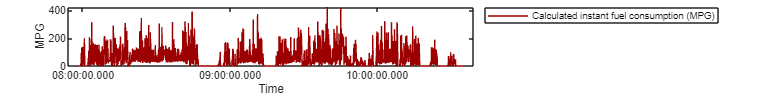

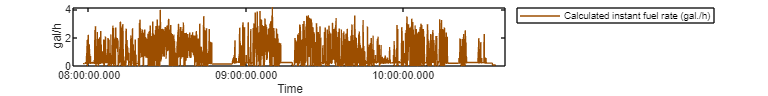

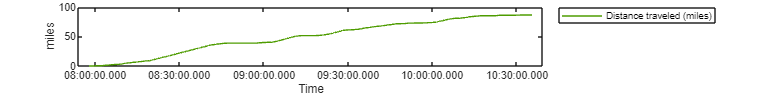

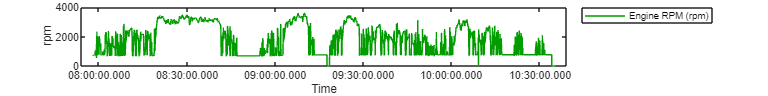

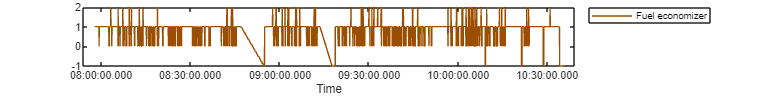

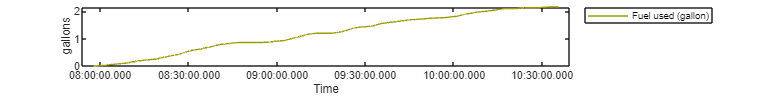

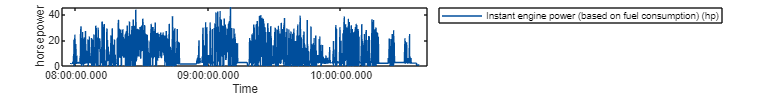

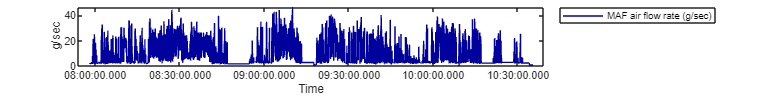

% Store the color of each plot
colors = {[153 0 0]./250, [153 76 0]./250, [76 153 0]./250, [0 153 0]./250, [153 76 0]./250, [153 153 0]./250, ...
          [0 76 153]./250, [0 0 153]./250, [76 153 0]./250, [153 0 153]./250, [153 0 76]./250, [64 64 64]./250};

% Store the ylabel of each plot
ylabels = {'MPG', 'gal/h', 'miles', 'rpm', '', 'gallons', 'horsepower', 'g/sec', '', '%', 'g', 'mph'};

% Plot each column 
for i = 2:width(data)
    figure('Position' , [0,0,800,100]);
    col = data.(i);
    label = data.Properties.VariableNames{i};
    plot(data.time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    legend(label, "Location","bestoutside")
end

### Create Box Plot of Select Measurments

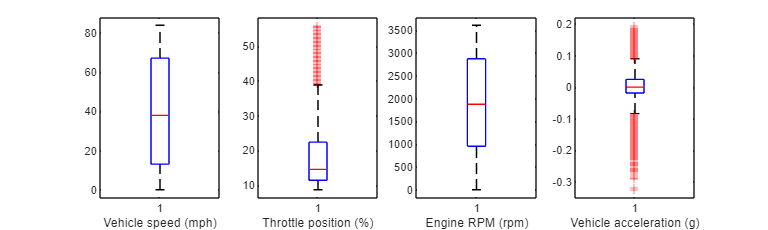

% Select the columns we want to plot
SelectColumns = ["Vehicle speed (mph)" "Throttle position (%)" "Engine RPM (rpm)" "Vehicle acceleration (g)"];

% Create the box plots
figure('Position', [0 0 1000 300])
for i = 1:length(SelectColumns)
    subplot(1,4,i)
    boxplot(data.(SelectColumns(i)))
    xlabel(SelectColumns(i))
end

### Create a Pair Plot of Select Measurments

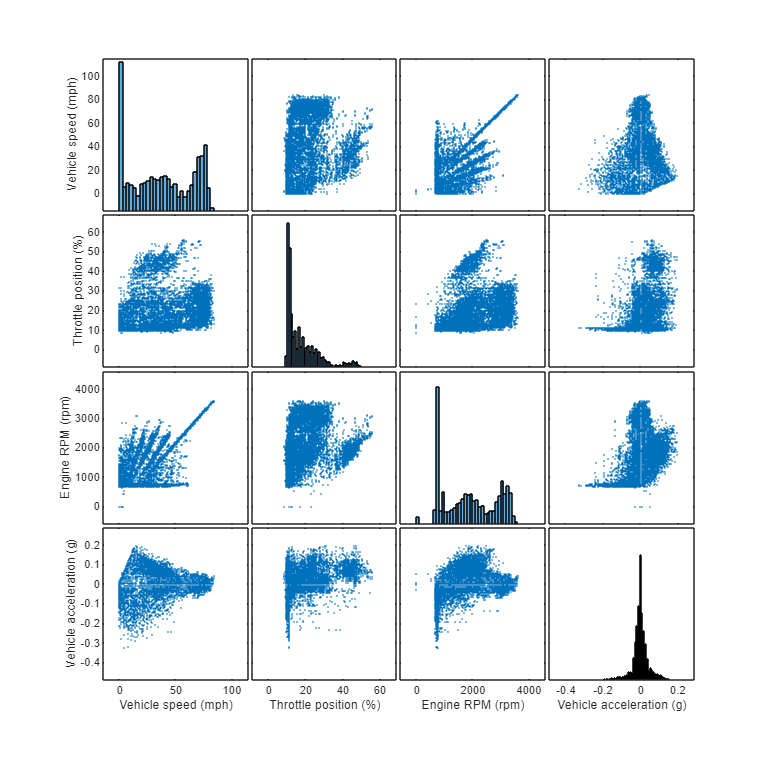

% Find the index of the columns we want to plot
idx = ones(1,length(SelectColumns)); % Create an array for the indices
for i = 1:length(SelectColumns)
    % Fill idx with the index of each desired column
    idx(i) = find(data.Properties.VariableNames == SelectColumns(i));
end 
PlotData = table2array(data(:,idx)); % Turn the table into an array for plotting

% Plot the data
figure('Position', [0,0,1000,1000]);
[~,AX] = plotmatrix(PlotData);
for i = 1:length(SelectColumns)
    ylabel(AX(i,1), SelectColumns(i))
    xlabel(AX(4,i), SelectColumns(i))
end

### Create a Heatmap of Select Measurments

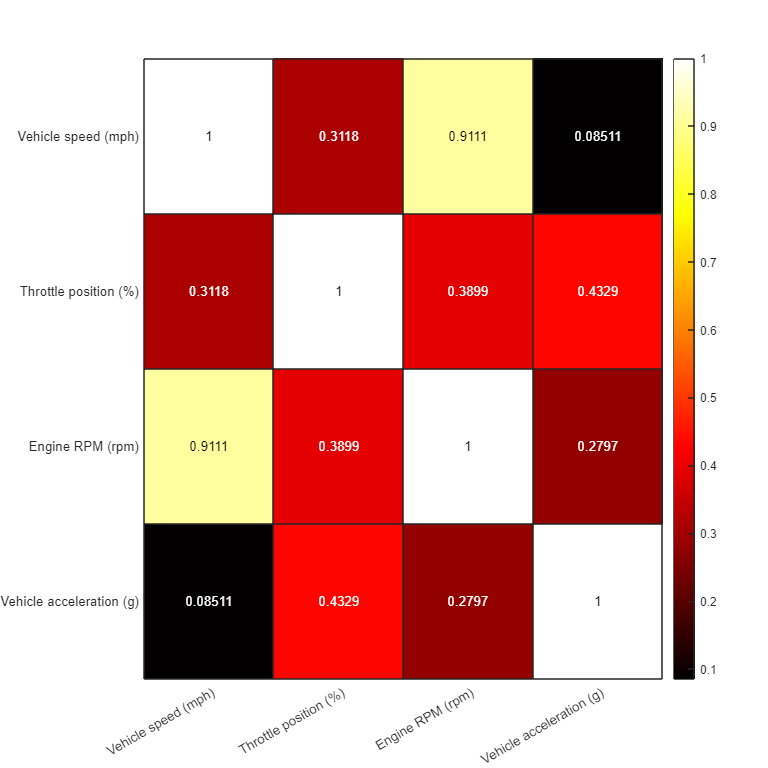

R = corrcoef(PlotData);
heatmap(R, "YDisplayLabels",SelectColumns, "XDisplayLabels", SelectColumns, 'Colormap', hot)

## Case Study 1: Automotive Catalytic Converter Lightoff Time

The catalyst light-off temperature is a minimum temperature to initiate the catalytic reaction. Before light-off temperature is reached, the catalytic converter is less effective at reducing the pollutants. A typical light-off temperature is between 400 to 600 degrees F. The normal operating temperature is between 750 to 1,600 degrees F. The operating temperature increases with more pollutants in the exhaust.

**Objective:** Calculate the time to catalyst light-off (500 degF) in seconds. Create an ARX model of the catalytic temperature and coolant temperature based on the vehicle speed and engine status.

### Import Data and View Columns

% Import data
url = "http://apmonitor.com/pds/uploads/Main/auto_warmup.txt";
data = readtable(url, "VariableNamingRule", "preserve");

% Print data columns
for i = 1:numel(data.Properties.VariableNames)
    column = data.Properties.VariableNames{i};
    disp(column)
end 

time
# warm-ups since codes cleared ()
A/C pressure (kPa)
Absolute load value (%)
Absolute pedal position D (%)
Absolute pedal position E (%)
Absolute throttle position B (%)
Air:fuel ratio ()
Ambient air temperature (℉)
Average fuel consumption (MPG)
Average fuel consumption (total) (MPG)
Average fuel consumption 10 sec (MPG)
Average speed (mph)
Barometric pressure (kPa)
Calculated boost (bar)
Calculated engine load value (%)
Calculated instant fuel consumption (MPG)
Calculated instant fuel rate (gal./h)
Catalyst temperature Bank 1 Sensor 1 (℉)
Commanded evaporative purge (%)
Commanded throttle actuator (%)
Control module voltage (V)
Distance traveled since codes cleared (miles)
Distance traveled with MIL on (miles)
Distance travelled (miles)
Distance travelled (total) (miles)
Engine coolant temperature (℉)
Engine RPM (rpm)
Ethanol fuel percent (%)
Evap. system vapor pressure (Pa)
Fuel economizer (based on fuel system status and throttle posit
Fuel level input (%) (%)
Fuel level input

% Select columns of interest
data1 = data.('Engine coolant temperature (℉)');
data1 = table(data.time, data1, 'VariableNames', {'time' 'Engine coolant'}); % Join time to data1

% Repeat for the second column of interest
data2 = data.('Catalyst temperature Bank 1 Sensor 1 (℉)');
data2 = table(data.time, data2, 'VariableNames', {'time' 'catalyst (degF)'});

% Repeat for the third column of interest
data3 = data.('Vehicle speed (mph)');
data3 = table(data.time, data3, 'VariableNames', {'time' 'speed (mph)'}); 

% Join data
data = outerjoin(data1, data2, 'Type', 'left', 'Keys', 'time'); % Join data1 and data2
data.time_data2 = []; % Remove the extra time column
data.Properties.VariableNames = ["time", "Engine coolant", "Catalyst temperature"]; % Rename the variables
data = outerjoin(data, data3, 'Type', 'left', 'Keys', 'time'); % Join data3

% Remove the extra time column
data.time_data3 = [];

% Assign variable names
data.Properties.VariableNames = {'Time' 'coolant (degF)', 'catalyst (degF)', 'speed (mph)'};

% Display a sample of the data
disp(data(1:10,:))

        Time        coolant (degF)    catalyst (degF)    speed (mph)
    ____________    ______________    _______________    ___________

    06:21:24.588         48.2                NaN             NaN    
    06:21:24.794          NaN                NaN             NaN    
    06:21:24.959          NaN                NaN               0    
    06:21:25.185          NaN                NaN             NaN    
    06:21:25.404          NaN              47.66             NaN    
    06:21:25.639          NaN                NaN             NaN    
    06:21:25.806          NaN                NaN             NaN    
    06:21:25.891          NaN                NaN             NaN    
    06:21:30.429          NaN                NaN             NaN    
    06:21:30.534          NaN                NaN             NaN    



% Forward fill missing values
data = ffill(data);

% Display the filled table
disp(data(1:10,:))

        Time        coolant (degF)    catalyst (degF)    speed (mph)
    ____________    ______________    _______________    ___________

    06:21:24.588         48.2              47.66              0     
    06:21:24.794         48.2              47.66              0     
    06:21:24.959         48.2              47.66              0     
    06:21:25.185         48.2              47.66              0     
    06:21:25.404         48.2              47.66              0     
    06:21:25.639         48.2              47.66              0     
    06:21:25.806         48.2              47.66              0     
    06:21:25.891         48.2              47.66              0     
    06:21:30.429         48.2              47.66              0     
    06:21:30.534         48.2              47.66              0     



disp(data(end-10:end,:))

        Time        coolant (degF)    catalyst (degF)    speed (mph)
    ____________    ______________    _______________    ___________

    06:55:42.358        201.2             1070.8              0     
    06:55:42.458        201.2             1070.8              0     
    06:55:42.605        201.2             1070.8              0     
    06:55:42.878        201.2             1070.8              0     
    06:55:43.002        201.2             1070.8              0     
    06:55:43.180        201.2             1070.8              0     
    06:55:43.328        201.2             1070.8              0     
    06:55:43.480        201.2             1070.8              0     
    06:55:43.658        201.2             1070.8              0     
    06:55:43.814        201.2             1070.8              0     
    06:55:43.975        201.2      

### Plot Data

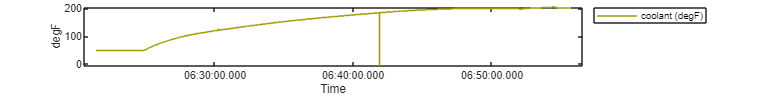

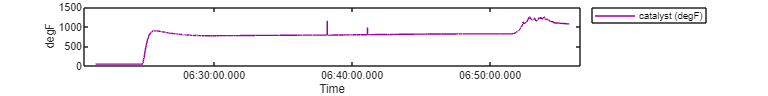

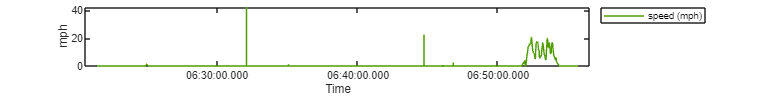

% Store the color of each plot
colors = {[153 153 0]./250, [153 0 153]./250, [76 153 0]./250};

% Store the ylabel of each plot
ylabels = {'degF', 'degF', 'mph'};

% Plot each column 
for i = 2:width(data)
    figure('Position' , [0,0,800,100]);
    col = data.(i);
    label = data.Properties.VariableNames{i};
    plot(data.Time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    legend(label, "Location","bestoutside")
end

### Remove Gross Outliers

The coolant temperature has a sudden spike to 0 degrees in the middle of the data which is likely an error. The speed also jumps a couple of times when the car isn't moving so those can be removed as well. In the last 5 minutes the car actually was driven to see how the temperature would change. 

% data cleansing
data = data(data.('coolant (degF)')>40,:);
data = data(data.('speed (mph)')<20,:);

Plotting the change in the temperatures will let us see how quickly the temperatures are changing and allow us to remove the spikes in the catalyst temperature data.

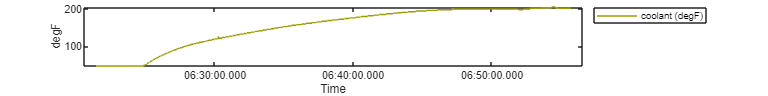

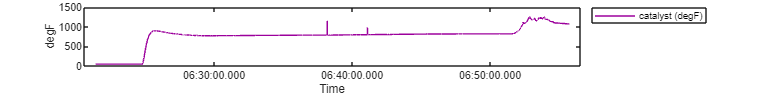

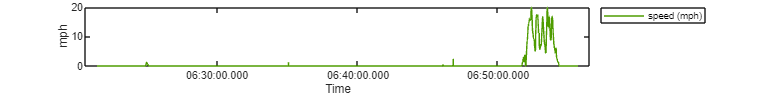

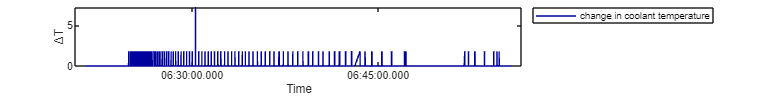

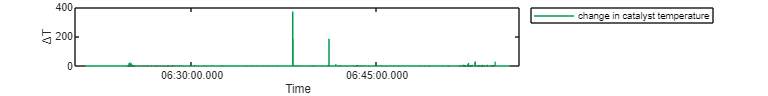

% Get the derivative of the coolant temperature
data.d1 = zeros(length(data.Time),1);
data.d1(2:end) = abs(diff(data.('coolant (degF)'))); 

% Get the change in the catalyst temperature
data.d2 = zeros(length(data.Time),1);
data.d2(2:end) = abs(diff(data.('catalyst (degF)')));

% Plot the data
% Store the color of each plot
colors = {[153 153 0]./250, [153 0 153]./250, [76 153 0]./250, [0 0 153]./250, [0 153 76]./250};

% Store the ylabel of each plot
ylabels = {'degF', 'degF', 'mph', 'ΔT', 'ΔT'};

% Plot each column 
for i = 2:width(data)
    figure('Position' , [0,0,800,100]);
    col = data.(i);
    label = data.Properties.VariableNames{i};
    plot(data.Time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    if label == "d1"
        label = "change in coolant temperature";
    elseif label == "d2"
        label = "change in catalyst temperature";
    end
    legend(label, "Location","bestoutside")
end

### Remove Other Outliers and Bad Speed Data

Now we'll remove some of the new outliers we see in the plots of the change in temperature. 

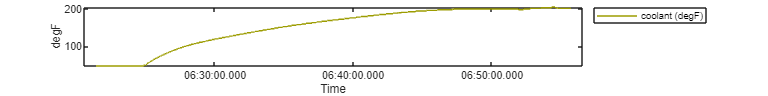

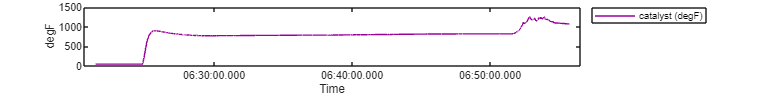

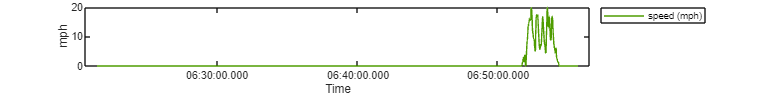

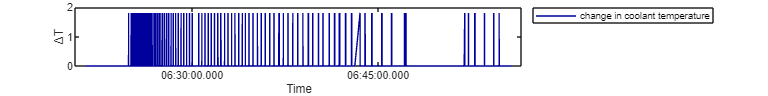

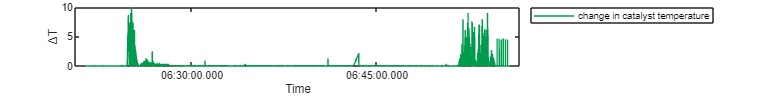

% 3 cycles because the catalyst temperature stays high for a few samples
for i = 1:3
    data.d1(2:end) = abs(diff(data.('coolant (degF)'))); 
    data.d2(2:end) = abs(diff(data.('catalyst (degF)')));
    data = data(data.d1<5,:);
    data = data(data.d2<10,:);
end 

% zero the speed between 6:30 and 6:50
time_min = minutes(data.Time);
idx = (time_min <= 410);
data.("speed (mph)")(idx) = 0;

% View the filtered data
% Store the color of each plot
colors = {[153 153 0]./250, [153 0 153]./250, [76 153 0]./250, [0 0 153]./250, [0 153 76]./250};

% Store the ylabel of each plot
ylabels = {'degF', 'degF', 'mph', 'ΔT', 'ΔT'};

% Plot each column 
for i = 2:width(data)
    figure('Position' , [0,0,800,100]);
    col = data.(i);
    label = data.Properties.VariableNames{i};
    plot(data.Time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    if label == "d1"
        label = "change in coolant temperature";
    elseif label == "d2"
        label = "change in catalyst temperature";
    end
    legend(label, "Location","bestoutside")
end

### Insert Feature (Engine On/Off) and Reduce Data

The data doesn't have a feature for when the engine is on or off so that will be added. 

% delete d1 and d2
try
    data.d1 = [];
    data.d2 = []; 
catch exception
    disp('Already Deleted')
end

% add engine state (on/off)
data.engine = zeros(size(data.Time));

% Find the rows between 'time_start' and 'time_end'
time_filter = (time_min >= 384.76) & (time_min <= 415);

% Set the 'engine' column to 1 for rows that satisfy the time condition
data.engine(time_filter) = 1;

### Display Cleansed Data

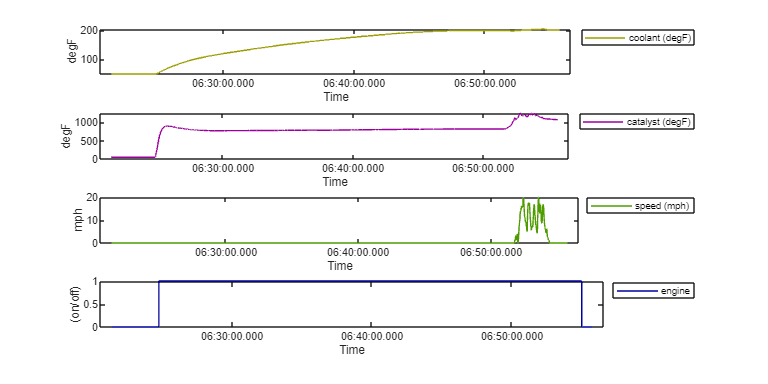

% Store the color of each plot
colors = {[153 153 0]./250, [153 0 153]./250, [76 153 0]./250, [0 0 153]./250};

% Store the ylabel of each plot
ylabels = {'degF', 'degF', 'mph', '(on/off)'};

% Plot each column 
figure('Position' , [0,0,800,400]);
for i = 2:width(data)
    subplot(width(data)-1,1,i-1)
    col = data.(i);
    label = data.Properties.VariableNames{i};
    plot(data.Time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    legend(label, "Location","bestoutside")
end

% Save the figure and the data
writetable(data, 'auto_clean.csv')
saveas(gcf, 'auto_warmup.png', 'png')

### Determine Time to Catalyst Light-off

% Get the columns of interest
select = [data.engine data.('catalyst (degF)')];

% Get the data index where the catalyst temperature rises above 500 degrees
idx = (time_min >= 384) & (time_min <= 386);

% Create a new variable for when the light-off temperature is reached
s = select(idx,:);
s = array2table(s, 'VariableNames', {'engine' 'catalyst (degF)'});
s.Time = data.Time(idx);

% Change the order of the variables
s = s(:, {'Time', 'engine', 'catalyst (degF)'});

% Create the catalyst light-off variable
s.('light-off') = s.('catalyst (degF)') > 500

s = 677×4 table
        Time        engine    catalyst (degF)    light-off
    ____________    ______    _______________    _________

    06:24:14.017      0            47.3            false  
    06:24:14.111      0            47.3            false  
    06:24:14.255      0            47.3            false  
    06:24:14.321      0            47.3            false  
    06:24:14.418      0            47.3            false  
    06:24:14.568      0            47.3            false  
    06:24:14.642      0            47.3            false  
    06:24:14.730      0            47.3            false  
    06:24:14.800      0            47.3            false  
    06:24:14.867      0            47.3            false  
    06:24:14.964      0            47.3            false  
    06:24:15.136      0            47.3            false  
    06:24:15.265     

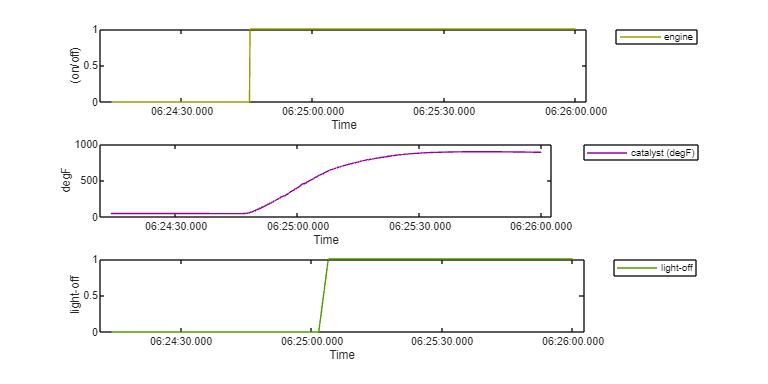

% Store the color of each plot
colors = {[153 153 0]./250, [153 0 153]./250, [76 153 0]./250};

% Store the ylabel of each plot
ylabels = {'(on/off)', 'degF', 'light-off'};

% Plot each column 
figure('Position' , [0,0,800,400]);
for i = 2:width(s)
    subplot(width(s)-1,1,i-1)
    col = s.(i);
    label = s.Properties.VariableNames{i};
    plot(s.Time, col, 'Color', colors{i-1})
    xlabel('Time')
    ylabel(ylabels{i-1})
    legend(label, "Location","bestoutside")
end

In the plot we can see where the engine turned on and where the catalyst light-off occurred, and there's only a short time inbetween the two. Using both of those times the time until catalyst light-off can be calculated exactly. 

% Find the the indicies where the engine turns on and light-off occurs 
engine_start = find(s.engine, 1, 'first');
light_off = find(s.('light-off'), 1, 'first');

% Find the time inbetween
time_sec = seconds(s.Time);
light_off_sec = time_sec(light_off) - time_sec(engine_start);
fprintf('%.2f seconds until catalyst light-off', light_off_sec)

18.19 seconds until catalyst light-off

% reduce data to about every 1-2 seconds
data = data(1:10:end, :);

% Create a seconds variable
data.tsec = data.Time - data.Time(1);
data.tsec = seconds(data.tsec);

% Delete Time
data.Time = [];

### ARX Model

An ARX model is a combination of an autoregressive model and an exogenous input model. This model is used to represent a dynamic system like this car. The speed and engine state will be used as inputs and the catalyst and coolant temperatures will be outputs.

% Store inputs and outputs
u = data(:,["speed (mph)" "engine"]);
y = data(:, ["catalyst (degF)" "coolant (degF)"]);

% Convert table data to arrays
u_array = table2array(u);
y_array = table2array(y);

% Create an iddata object
data_mod = iddata(y_array, u_array, mean(diff(data.tsec)), ...
                  'InputName', ["Speed" "Engine"], 'OutputName', ["Catalyst" "Coolant"])

data_mod =

Time domain data set with 1322 samples.
Sample time: 1.55884 seconds            
                                        
Outputs        Unit (if specified)      
   Catalyst                             
   Coolant                              
                                        
Inputs         Unit (if specified)      
   Speed                                
   Engine                               
                                        



% Define orders and delay
na = [2 2;2 2];
nb = na;
nk = [1 1; 1 1];

% Create the arx model using the data and the previously established
% polynomial orders and input-output delay
arx_model = arx(data_mod, [na nb nk])

arx_model =
Discrete-time ARX model:                                                      
  Model for output "Catalyst": A(z)y_1(t) = - A_i(z)y_i(t) + B(z)u(t) + e_1(t)
    A(z) = 1 - 1.626 z^-1 + 0.6294 z^-2                                       
                                                                              
    A_2(z) = 1.049 z^-1 - 1.048 z^-2                                          
                                                                              
    B1(z) = 0.4648 z^-1 - 0.386 z^-2                                          
                                                                              
    B2(z) = 4.389 z^-1 - 0.8423 z^-2                                          
                                                                              
  Model for output "Coolant": A(z)y_2(t) = - A_i(z)y_i(t) + B(z)u(t) + e_2(t)
    A(z) = 1 - 0.8298 z^-1 - 0.1673 z^-2                                     
                                          

The results are plotted below with a prediction horizon of 4, meaning there are 4 time samples between the timepoint of each output measurement and the timepoint of the resulting predicted response. Both the coolant and catalyst temperature predictions are fairly accurate.

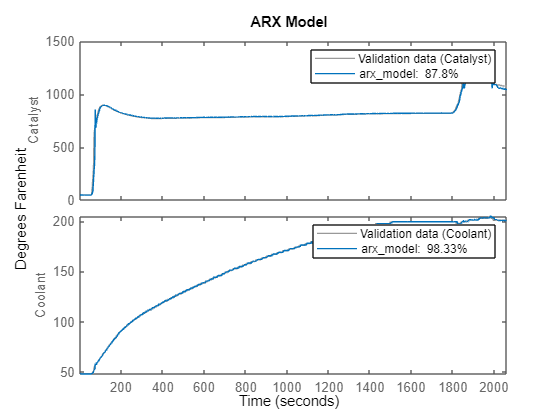

% Plot the results
figure;
compare(data_mod, arx_model, 4)
title('ARX Model')
ylabel('Degrees Farenheit')

## Case Study 2: GIS Map Visualization

**Objective:** Visualize the speed and elevation on a map. Geographic Information Systems (GIS) are an important technology to view spatially distributed data. The GIS maps can help to identify factors related to location.

### Import Data and View Columns

% Read the data into a table
zipFile = 'AutoTrip.zip';
if ~exist(zipFile, 'file')
    url = 'http://apmonitor.com/pds/uploads/Main/auto_trip.zip';
    websave(zipFile, url);
    unzip(zipFile);
end
data = readtable('auto_trip.csv', 'VariableNamingRule', 'preserve');

% Display the columns 
for i = 1:length(data.Properties.VariableNames)
    col = data.Properties.VariableNames{i};
    disp(col)
end

time
Absolute load value (%)
Absolute pedal position D (%)
Altitude (GPS) (feet)
Ambient air temperature (℉)
Average fuel consumption (MPG)
Average fuel consumption (total) (MPG)
Average fuel consumption 10 sec (MPG)
Average speed (mph)
Average speed (GPS) (mph)
Barometric pressure (kPa)
Calculated boost (bar)
Calculated engine load value (%)
Calculated instant fuel consumption (MPG)
Calculated instant fuel rate (gal./h)
Catalyst temperature Bank 1 Sensor 1 (℉)
Distance to empty (miles)
Distance travelled (miles)
Distance travelled (total) (miles)
Engine coolant temperature (℉)
Engine RPM (rpm)
Fuel economizer (based on fuel system status and throttle posit
Fuel level input (%) (%)
Fuel level input (V) (gallon)
Fuel used (gallon)
Fuel used (total) (gallon)
Fuel used price ($)
Fuel used price (total) ($)
Fuel/Air commanded equivalence ratio ()
Instant engine power (based on fuel consumption) (hp)
Intake air temperature (℉)
MAF air flow rate (g/sec)
Oxygen sensor 1 Wide Range Current (mA

% View a sample of the data
data(1:10,:)

ans = 10×41 table
        time        Absolute load value (%)    Absolute pedal position D (%)    Altitude (GPS) (feet)    Ambient air temperature (℉)    Average fuel consumption (MPG)    Average fuel consumption (total) (MPG)    Average fuel consumption 10 sec (MPG)    Average speed (mph)    Average speed (GPS) (mph)    Barometric pressure (kPa)    Calculated boost (bar)    Calculated engine load value (%)    Calculated instant fuel consumption (MPG)    Calculated instant fuel rate (gal./h)    Catalyst temperature Bank 1 Sensor 1 (℉)    Distance to empty (miles)    Distance travelled (miles)    Distance travelled (total) (miles)    Engine coolant temperature (

### Select Columns of Interest and Fill the Data

% Make a table with latitude and longitude
x = [data.Latitude data.Longitude, data.("Altitude (GPS) (feet)"), data.("Speed (GPS) (mph)")];
x = array2table(x, "VariableNames", {'Latitude', 'Longitude', 'Elevation', 'Speed'});

% Cut the data down to reduce processing time
x = x(1:130:end, :);

% Forward fill missing values
x = ffill(x);

% Check for missing values
check = isnan(table2array(x));
disp(sum(check,'all'))

     0



### Plot Data

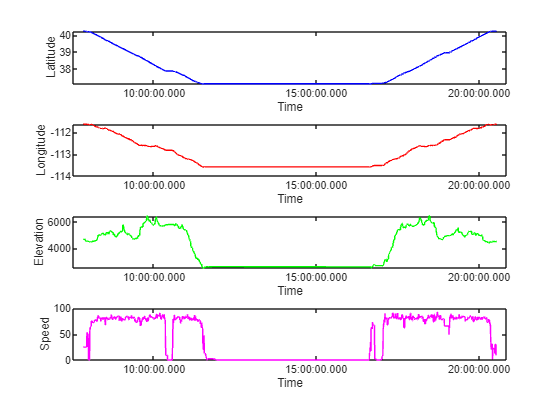

figure;
colors = {'blue', 'red', 'green', 'magenta'};
for i = 1:width(x)
    subplot(width(x),1,i)
    col = x.Properties.VariableNames{i};
    plot(data.time(1:130:end), x.(col), colors{i})
    xlabel('Time')
    ylabel(col)
end

Plotting latitude and longitude like this isn't helpful for knowing location. Plotting the points on a map will help us better understand where the driver is. 

### View GPS Points on Map

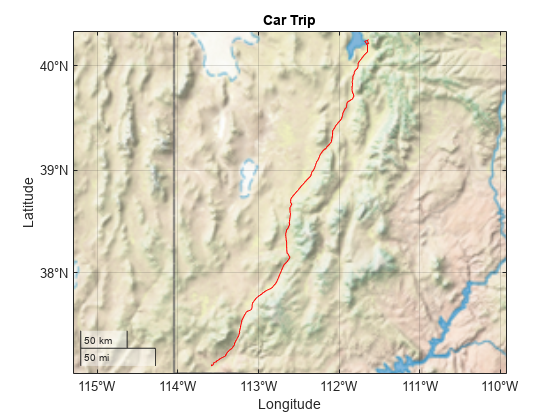

% Create figure
figure;

% Plot latitude and longitude values
geoplot(x.Latitude, x.Longitude, 'r-')

% Make a title and select the type of map
title('Car Trip')
geobasemap('landcover')

### Plot Elevation

The following figure will sort the the data into three levels of elevation and then plot the higher elevations with larger marker sizes. 

% Create figure
figure;

% Sort the elevation data
ela = x.("Elevation");
ela = sort(ela, 'ascend');
num = int32(length(ela)/3);
low = ela(num);
high = ela(num * 2);
el_low = (x.('Elevation') < low);
el_mid = (x.('Elevation') > low) & (x.('Elevation') < high);
el_high = (x.('Elevation') > high);
index = {el_low, el_mid, el_high};

% Store latitude and longitude values in a geoshape
shape = geoshape();
for k = 1:length(index)
    shape = append(shape, ... 
        x.Latitude(index{k}), x.Longitude(index{k}))
end

shape =  1×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


shape =  2×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
  (2 features concatenated with 1 delimiter)
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


shape =  3×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
  (3 features concatenated with 2 delimiters)
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


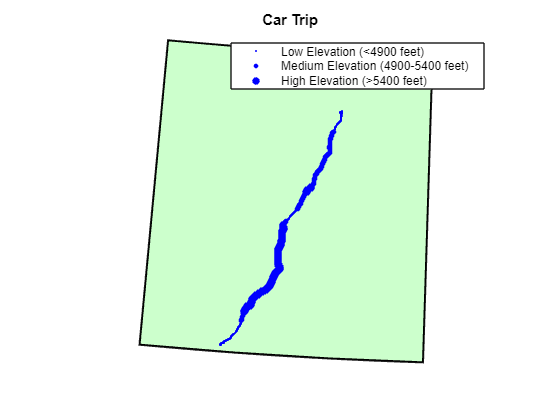


% Store marker size values
m_size = {1,3,5};

% Create the figure and the map
figure; 
ax = worldmap('North America');

% Set latitude and longitude boundaries
latlim = [37 41];
lonlim = [-115 -110];
setm(ax, 'MapLatLimit', latlim, 'MapLonLimit', lonlim);

% Show the data points
geoshow(ax, 'landareas.shp', 'FaceColor', [0.8 1 0.8]);
for k = 1:length(index)
    geoshow(shape(k).Latitude, shape(k).Longitude, 'DisplayType', 'point', ...
        'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'blue',...
        'MarkerSize', m_size{k}, 'Marker', 'o')
end

% Make a title
title('Car Trip')
legend({'' 'Low Elevation (<4900 feet)' 'Medium Elevation (4900-5400 feet)' 'High Elevation (>5400 feet)'})

### Plot Speed

The following figure will sort the the data into three levels of speed and then plot them with different colors.

% Create figure
figure;

% Sort the elevation data
spe = x.('Speed');
spe = sort(spe, 'ascend');
num = int32(length(spe)/3);
low = spe(num/3);
high = spe(num * 2);
spe_low = (x.('Speed') < low);
spe_mid = (x.('Speed') > low) & (x.('Speed') < high);
spe_high = (x.('Speed') > high);
index = {spe_low, spe_mid, spe_high};

% Store latitude and longitude values in a geoshape
shape = geoshape();
for k = 1:length(index)
    shape = append(shape, ... 
        x.Latitude(index{k}), x.Longitude(index{k}))
end

shape =  1×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


shape =  2×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
  (2 features concatenated with 1 delimiter)
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


shape =  3×1 geoshape vector with properties:

 Collection properties:
     Geometry: 'line'
     Metadata: [1×1 struct]
 Vertex properties:
  (3 features concatenated with 2 delimiters)
     Latitude: [40.2497 40.2488 40.2484 40.2479 40.2472 40.2456 40.2446 40.2432 40.2430 40.2430 40.2430 40.2428 40.2414 40.2396 40.2378 40.2357 40.2341 40.2332 40.2315 40.2301 40.2298 40.2288 40.2271 40.2256 40.2253 40.2253 40.2243 40.2225 40.2207 … ]
    Longitude: [-111.6356 -111.6353 -111.6364 -111.6378 -111.6378 -111.6378 -111.6378 -111.6378 -111.6387 -111.6408 -111.6427 -111.6433 -111.6433 -111.6433 -111.6433 -111.6433 -111.6434 -111.6433 -111.6430 -111.6429 -111.6429 -111.6429 -111.6428 … ]


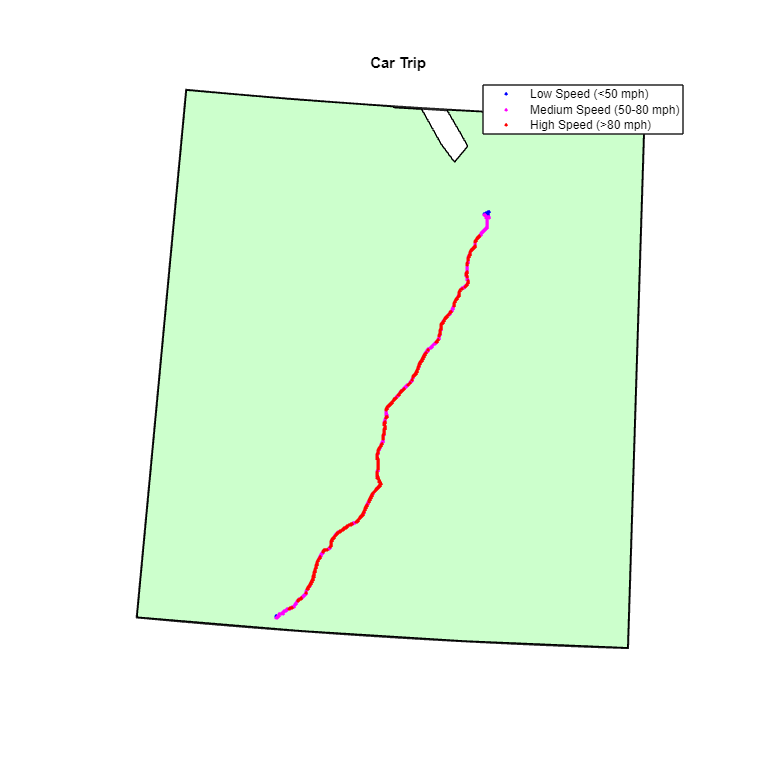

% Store color values
colors = {'blue', 'magenta', 'red'};

% Create the figure and the map
figure('Position', [0,0,1500,1500]); 
ax = worldmap('North America');

% Set latitude and longitude boundaries
latlim = [37 41];
lonlim = [-115 -110];
setm(ax, 'MapLatLimit', latlim, 'MapLonLimit', lonlim);

% Show the data points
geoshow(ax, 'landareas.shp', 'FaceColor', [0.8 1 0.8]);
for k = 1:length(index)
    geoshow(shape(k).Latitude, shape(k).Longitude, 'DisplayType', 'point', ...
        'MarkerEdgeColor', colors{k}, 'MarkerFaceColor', colors{k}, ...
        'MarkerSize', 2, 'Marker', 'o')
end
% Make a title
title('Car Trip')
legend({'' 'Low Speed (<50 mph)' 'Medium Speed (50-80 mph)' 'High Speed (>80 mph)'})

The driver only drives slow in the residential areas where he stops and ends. He keeps a medium to high speed all along the highway between the two cities. 

## Case Study 3: Fuel Efficiency Versus Speed

**Objective:** Calculate the fuel efficiency in miles per gallon (MPG) or Liters per 100 km (L/100 km). Use regression to develop a model of how measured factors relate to the fuel efficiency.

### Import Data and Display Columns Names

% Read the data into a table
url = 'http://apmonitor.com/pds/uploads/Main/automotive.txt';
data = readtable(url, 'VariableNamingRule', 'preserve');

% Display the columns 
for i = 1:length(data.Properties.VariableNames)
    col = data.Properties.VariableNames{i};
    disp(col)
end

time
Average fuel consumption (MPG)
Average fuel consumption (total) (MPG)
Average fuel consumption 10 sec (MPG)
Average speed (mph)
Calculated instant fuel consumption (MPG)
Calculated instant fuel rate (gal./h)
Distance travelled (miles)
Distance travelled (total) (miles)
Engine RPM (rpm)
Fuel economizer (based on fuel system status and throttle posit
Fuel used (gallon)
Fuel used (total) (gallon)
Fuel used price ($)
Fuel used price (total) ($)
Instant engine power (based on fuel consumption) (hp)
MAF air flow rate (g/sec)
Oxygen sensor 1 Wide Range Current (mA) (mA)
Oxygen sensor 1 Wide Range Equivalence ratio ()
Throttle position (%)
Vehicle acceleration (g)
Vehicle speed (mph)


% Rename a column
data.Properties.VariableNames{6} = 'MPG';

### Plot and Visualize the Data

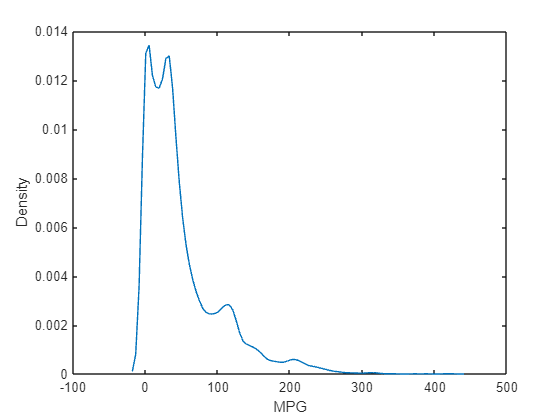

% Create a density plot of MPG
[f, xi] = ksdensity(data.MPG);
figure;
plot(xi,f)
xlabel('MPG')
ylabel('Density')

The majority of the time mpg is between 0 and 50. The higher values is likely when the car is coasting. 

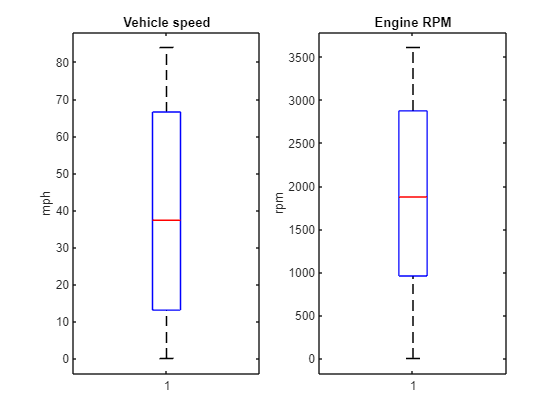

% Create boxplots of vehicle speed and engine rpm
figure;
vars = {'Vehicle speed (mph)', 'Engine RPM (rpm)'};
titles = {'Vehicle speed', 'Engine RPM'};
labels = {'mph', 'rpm'};
for i = 1:length(vars)
    subplot(1, length(vars), i)
    boxplot(data.(vars{i}))
    title(titles{i})
    ylabel(labels{i})
end

### Reformat Data

Use Vehicle Speed, Acceleration, and RPM as features. Visualize the effects of well-known aspects of driving on fuel efficiency.

datan = table(data.('Engine RPM (rpm)'), data.('Vehicle speed (mph)'), data.('Vehicle acceleration (g)'), data.MPG, ...
              'VariableNames', {'rpm', 'speed', 'acceleration', 'MPG'});

% Forward fill missing values
datan = ffill(datan);

% Remove bad or unuseful data
datan = datan(datan.MPG > 0,:); % Remove all the negative MPG values
datan = datan(datan.MPG < 45,:); % MPG higher than 45 is likely coasting

% Display a sample of the data
disp(datan(1:10,:))

    rpm      speed     acceleration      MPG  
    ____    _______    ____________    _______

     922    0.62137     0.0094281      0.92405
    1145    0.62137     0.0094281      0.92405
    1145    0.62137     0.0094281      0.92405
    1145    0.62137     0.0094281      0.92405
    1145    0.62137     0.0094281      0.92405
    1145     1.8641      0.028576       8.4511
    1092     1.8641      0.028576       8.4511
    1092     1.8641      0.028576       8.4511
    1092     1.8641      0.028576       8.4511
    1092     1.8641      0.028576       8.4511



### Create a Heatmap

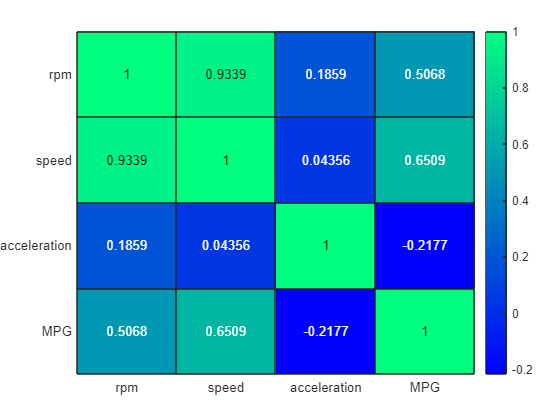

figure;
R = corrcoef(table2array(datan));
heatmap(R, "YDisplayLabels", datan.Properties.VariableNames, ...
        "XDisplayLabels", datan.Properties.VariableNames, 'Colormap', winter)

Speed and rpm have the highest correlation which makes sense, raising the rpm increases the speed of the car. Speed and mpg also have a relatively high correlation. 

### Create a Pairplot

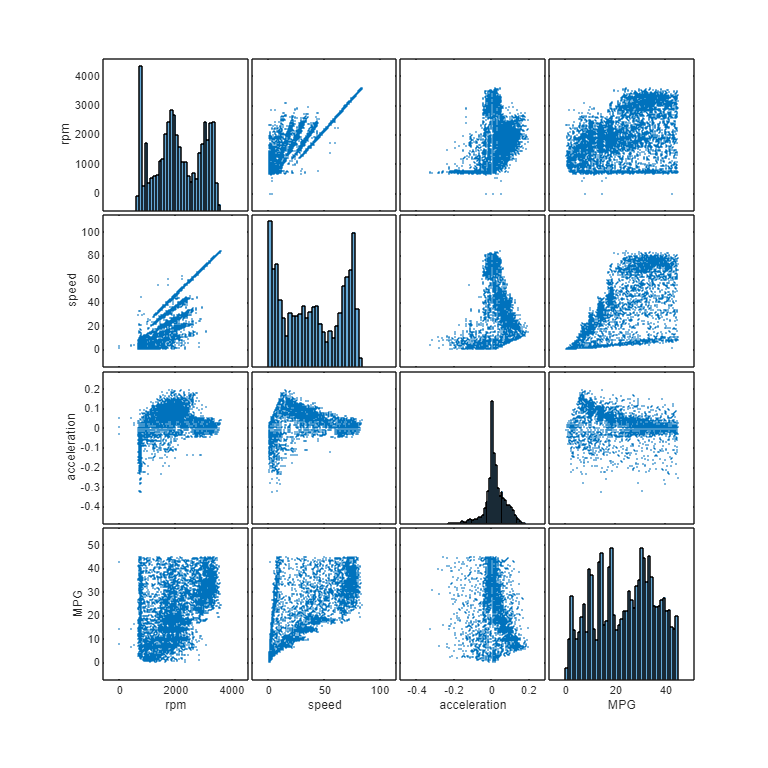

% Plot the data
figure('Position', [0,0,1000,1000]);
[~,AX] = plotmatrix(table2array(datan));
vars = datan.Properties.VariableNames;
for i = 1:length(vars)
    ylabel(AX(i,1), vars{i})
    xlabel(AX(length(vars),i), vars{i})
end

We can see the correlations that appear in the heatmap here in the pairplot. Higher speed tends to raise mpg and higher rpm raises speed. You can also see the gear changes in the rpm and speed plot, the speed and rpm will raise until the gear changes and rpm drops, then rpm incrases again with a higher speed. 

### Scale and Split Data

% Scale data
mu = ones(1,length(vars));
sigma = ones(1,length(vars));
data_sca = table();

for i = 1:length(vars)
    [data_sca.(vars{i}), mu(i), sigma(i)] = zscore(datan.(vars{i}));
end

% Create an index for splitting data
cv = cvpartition(length(datan.rpm), 'Holdout', 0.2);
train_idx = training(cv);
test_idx = test(cv);

% Split data
x_train = data_sca(train_idx, 1:end-1);
x_test = data_sca(test_idx, 1:end-1);
y_train = data_sca.MPG(train_idx);
y_test = data_sca.MPG(test_idx);

### Train LSBoost Model

mdl = fitrensemble(x_train, y_train, 'Method', 'LSBoost');

% make predictions on testing set
y_pred = predict(mdl, x_test);

% evaluate model performance
R2 = 1 - sum((y_test - y_pred).^2)/sum((y_test - mean(y_test)).^2);
fprintf('R2 = %.2f\n', R2);

R2 = 0.83


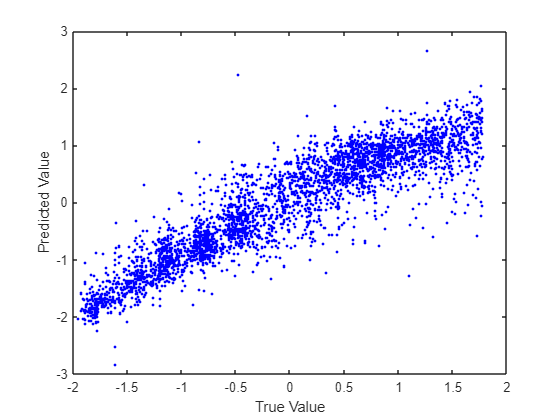

% Assess the results in a plot
figure;
plot(y_test, y_pred, 'b.')
xlabel('True Value')
ylabel('Predicted Value')

### Train Neural Network

mdl_net = fitrnet(x_train, y_train)

mdl_net =   RegressionNeuralNetwork
           PredictorNames: {'rpm'  'speed'  'acceleration'}
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 18145
               LayerSizes: 10
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [752×7 table]


  Properties, Methods



% make predictions on testing set
y_pred_net = predict(mdl_net, x_test);

% evaluate model performance
R2 = 1 - sum((y_test - y_pred_net).^2)/sum((y_test - mean(y_test)).^2);
fprintf('R2 = %.2f\n', R2);

R2 = 0.68


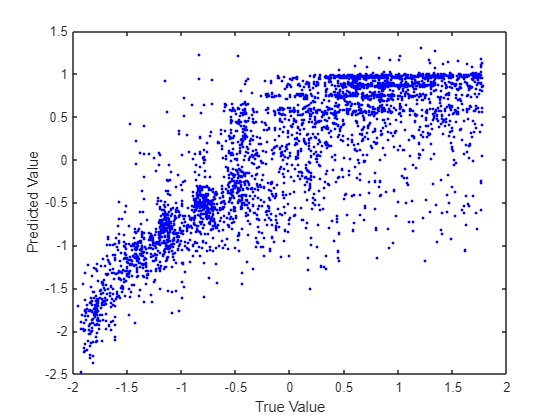

% Assess the results in a plot
figure;
plot(y_test, y_pred_net, 'b.')
xlabel('True Value')
ylabel('Predicted Value')

### Display Extrapolations with One Variable

The LSBoost model performed better than the neural network so we will use the LSBoost model to predict how each variable affects fuel efficiency. Each prediction will use an input of the median of two variables and a range of values of one variable. The variable with a range of values is then plotted against the predicted values to see how it affects fuel efficiency. 

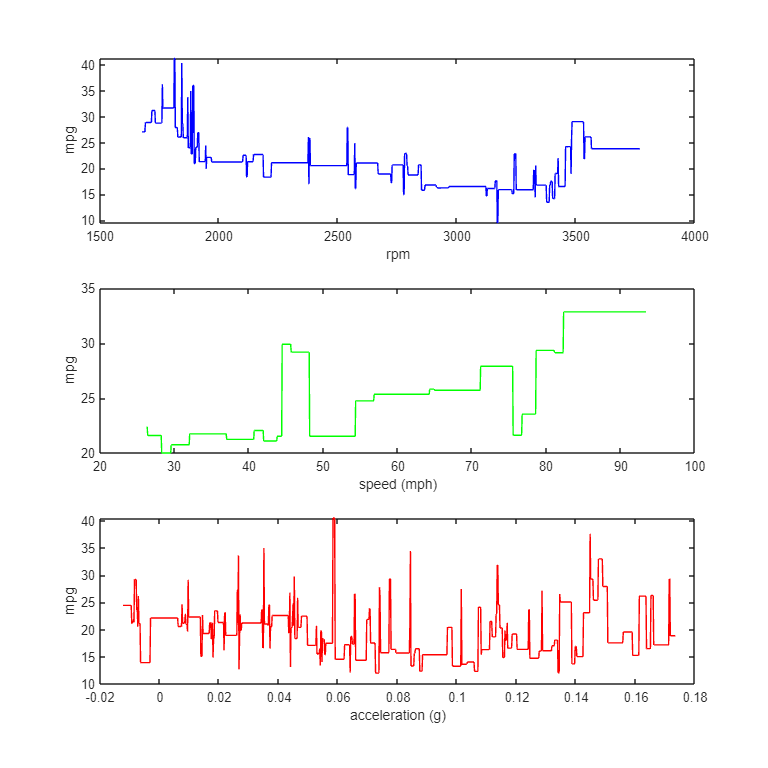

% Make a range of data points for each feature
n = 1000;
rpmvar = linspace(-0.5, 2, n);
speedvar = linspace(-0.5,2,n);
acelvar = linspace(-0.5,2.5,n);

% Create median value arrays for each feature
rpmmed = ones(n,1) * median(data_sca.rpm);
speedmed = ones(n,1) * median(data_sca.speed);
acelmed = ones(n,1) * median(data_sca.acceleration);

% Make tables for each feature
rpm_tbl = table(rpmvar', speedmed, acelmed, 'VariableNames' , {'rpm', 'speed', 'acceleration'});
speed_tbl = table(rpmmed, speedvar', acelmed, 'VariableNames' , {'rpm', 'speed', 'acceleration'});
acel_tbl = table(rpmmed, speedmed, acelvar', 'VariableNames' , {'rpm', 'speed', 'acceleration'});

% Make predictions
rpm_pred = predict(mdl, rpm_tbl);
speed_pred = predict(mdl, speed_tbl);
acel_pred = predict(mdl, acel_tbl);

% Unscale predictions
rpm_pred = (rpm_pred .* sigma(4)) + mu(4);
speed_pred = (speed_pred .* sigma(4)) + mu(4);
acel_pred = (acel_pred .* sigma(4)) + mu(4);
pred = {rpm_pred speed_pred acel_pred};

% Unscale features
rpmvar = (rpmvar .* sigma(1)) + mu(1);
speedvar = (speedvar .* sigma(2)) + mu(2);
acelvar = (acelvar .* sigma(3)) + mu(3);
vars = {rpmvar speedvar acelvar};

% Plot the results
figure('Position', [0,0,1000,1000]);
labels = {'rpm' 'speed (mph)' 'acceleration (g)'};
colors = {'b-', 'g-', 'r-'};
num = length(vars);
for i = 1:num
    subplot(num,1,i)
    plot(vars{i}, pred{i}, colors{i})
    xlabel(labels{i})
    ylabel('mpg')
end

### Analysis

Some of these results are not causal but depend on the car. For example, this car has a manual transmission so the results could be different for an automatic vehicle. The general trends of the charts is that higher rpm decreases fuel efficiency, higher speed raises fuel efficiency, and higher acceleration decreases fuel efficiency. 

function data_filled = ffill(x)
        % Forward fill missing values
    
    for i = 1:width(x) % Run through each column of the data
        column = x.(i); % Set column equal to the current column
        loc = 1; % Create a value for an index the data is filled 
    
        while loc < length(column) % Run until loc reaches the end of the column
            idx = isnan(column); % Make idx the indices of NaN in the column
            ind = find(idx, 1, 'first'); % Find the index of the NaN value
    
            if ~isempty(ind) % If ind isn't empty set loc equal to the index before the NaN
                loc = ind(1)-1;
    
                if loc == 0 % If the first value is NaN fill with the first numerical value
                    loc = find(~idx, 1, 'first');
                end
                
                column(ind) = column(loc); % Set the NaN value to the most recent value
            end
    
            check = isnan(column);
            if sum(check,'all') == 0 % If there are no more NaN values end the loop
                loc = length(column);
            end
    
        end
    
        x.(i) = column; % Replace data with the new values
    end
    data_filled = x;
end